clear;

A = [25 6 -20 11;
    14 3 -10 4;
    40 11 -31 17;
    6 4 -4 3];

C = [1 0 -1 1];
x0 = [1; 1; 1; 1];
xh0 = [0; 0; 0; 0];

%L = [1; 1; 1; 1];



%{
t = 0:0.0001:2;
f = [ 0.5*sin(2*pi*0.1*t);
    0.3*cos(2*pi*0.2*t);
    0.4*sin(2*pi*0.15*t + pi/4);
    0.2*cos(2*pi*0.05*t)];

xi = 0.1*sin(2*pi*0.3*t) + 0.05*cos(2*pi*0.25*t);
%}
%============================================================
nu = 1;
Q = eye(4);
R = 1;
alpha = 10;
aQ = alpha * Q;
aR = alpha * R;
%===================L1======================================
[P1,~,K] = icare(A', C', Q, R, [], [], [], nu);

disp("Determinant of P1");

Determinant of P1


disp(det(P1));

   5.1823e+03




disp("P1");

P1


disp(P1);

   63.4984   37.9508  130.6814   76.4226
   37.9508   28.6271   78.9099   44.0316
  130.6814   78.9099  283.8838  179.6160
   76.4226   44.0316  179.6160  127.6773




L1 = -P1* C' * inv(R);
disp("L1");

L1


disp(L1);

   -9.2395
   -3.0726
  -26.4137
  -24.4839




%=================L2========================================
[P2,~,K] = icare(A', C', aQ, R, [], [], [], nu);

disp("Determinant of P2");

Determinant of P2


disp(det(P2));

   1.3521e+06




disp("P2");

P2


disp(P2);

   1.0e+03 *

    0.4769    0.3002    0.9222    0.4783
    0.3002    0.2010    0.5855    0.3038
    0.9222    0.5855    1.8402    0.9989
    0.4783    0.3038    0.9989    0.5812




L2 = -P2* C' * inv(R);
disp("L2");

L2


disp(L2);

  -33.0665
  -18.4427
  -80.8288
  -60.6352




%====================L3=====================================
[P3,~,K] = icare(A', C', Q, aR, [], [], [], nu);

disp("Determinant of P3");

Determinant of P3


disp(det(P3));

   4.8828e+05




disp("P3");

P3


disp(P3);

   92.0913   37.3332  190.4522  118.3935
   37.3332   61.1155   84.5025   36.1468
  190.4522   84.5025  450.6701  335.7674
  118.3935   36.1468  335.7674  312.1042




L3 = -P3* C' * inv(aR);
disp("L3");

L3


disp(L3);

   -2.0033
    1.1022
   -7.5549
   -9.4730




%====================L4=====================================
[P4,~,K] = icare(A', C', aQ, aR, [], [], [], nu);

disp("Determinant of P4");

Determinant of P4


disp(det(P4));

   5.1823e+07




disp("P4");

P4


disp(P4);

   1.0e+03 *

    0.6350    0.3795    1.3068    0.7642
    0.3795    0.2863    0.7891    0.4403
    1.3068    0.7891    2.8388    1.7962
    0.7642    0.4403    1.7962    1.2768




L4 = -P4* C' * inv(aR);
disp("L4");

L4


disp(L4);

   -9.2395
   -3.0726
  -26.4137
  -24.4839



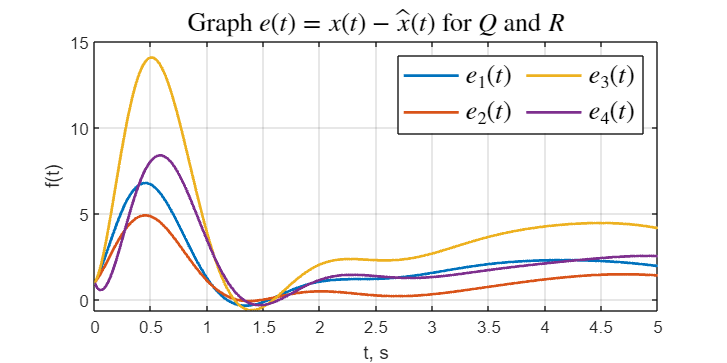


%===========Modeling==================================


L=L1;

open_system('task_2_simm');
set_param('task_2_simm/x', 'VariableName', 'x')
set_param('task_2_simm/xh', 'VariableName', 'xh')
set_param('task_2_simm/e', 'VariableName', 'e')

out = sim('task_2_simm');

figure('Position', [100 100 800 400])
plot(out.e,'-', 'LineWidth',1.5);
%hold on
%plot(out.xh,'--', 'LineWidth',1.5);

grid()
title('Graph $e(t) = x(t) - \hat{x}(t)$ for $Q$ and $R$','Interpreter','latex',  'FontSize', 14)
legend('$e_1(t)$', '$e_2(t)$', '$e_3(t)$', '$e_4(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')

%hold off

%{
figure('Position', [100 100 800 400])
plot(out.x,'-', 'LineWidth',1.5);
hold on
plot(out.xh,'--', 'LineWidth',1.5);

grid()
title('Graph $x(t)$ and $\hat{x}(t)$ for $\alpha Q$ and $\alpha R$','Interpreter','latex',  'FontSize', 14)
legend('$x_1(t)$', '$x_2(t)$', '$x_3(t)$', '$x_4(t)$', ...
    '$\hat{x}_1(t)$', '$\hat{x}_2(t)$', '$\hat{x}_3(t)$', '$\hat{x}_4(t)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('f(t)')
xlabel('t, s')
hold off
%}
